# MATLAB_Tutor_Week2

## 一.字符数组和字符串数组

        在R2016b版本之后，Matlab引入了字符串数组**string**，可以用字符数组而不是字符串数组来表示文本。只有一个字符串的字符串数组也可称为字符串标量。

- **字符数组：**

char_array = 'THU EESAST'

- **字符串数组：**

string_array = "THU EESAST"

        尽管在大多数时候可以通用，两者仍有一些区别需要注意。

### 1.创建

        如上面的例子，可以直接使用引号创建字符数组(单引号)或字符串数组(双引号)。

char_array1 = 'THU EESAST'
string_array1 = "THU EESAST"

### 2.互相转换

        字符串数组与字符数组之间可以互相转换。

#### 2.1.字符串数组转换为字符数组

对于单个字符串即字符串标量，使用char()函数进行转换，会得到一个$1\times N$的字符向量：

string_array2 = "string to char"
strlength(string_array2)
char_array2 = char(string_array2)
size(char_array2)

但是对于有字符串的字符串数组，情况则会发生变化：

- **字符串列向量：**

string_array3 = ["string1";"string2";"string3"]
char_array3 = char(string_array3)

- **字符串行向量：**

string_array4 = ["string1","string2","string3"]
char_array4 = char(string_array4)

- **字符串矩阵(其实知道前两个例子的规律后，很容易推出这个例子的输出形式)：**

string_array5 = ["string1","string2","string3";"string4","string5","string6"]
char_array5 = char(string_array5)

#### 2.2.字符数组转换为字符串数组

**        请注意对比转换前后的size变化。**

- **行向量：**

char_array6 = 'char' %完全等价于 char_array6 = ['c','h','a','r']
string_array6 = string(char_array6)

- **列向量：**

char_array7 = ['a';'b';'c';'d']
string_array7 = string(char_array7)

### 3.两者的行为区别

#### 3.1.减去一个数字或字符

char_array8 = 'abcdefg';
string_array8 = "abcdefg";
char_array8 - 'a'
char_array8 - 97
%可以逐条尝试执行下面几行代码
%char_array8 - "a"  
%string_array8 - 'a'
%string_array8 - "a"
%string_array8 - 97

#### 3.2.将字符串数组或字符数组相加

- **字符数组**会得到Unicode码相加的结果：

char_array9 = 'THU EESAST';
char_array10 = '!';
char_array9 + char_array10

- **字符串数组**会将两端字符串拼接起来：

string_array9 = "THU EESAST";
string_array10 = "!";
string_array9 + string_array10

#### 3.3.将内容为数字的文本转换为double等类型

- **字符数组**会得到对应字符的Unicode编码：

char_array11 = ['123';'1e2';'1.2'];
char_array12 = '123 456 789';
double(char_array11)
double(char_array12)

- **字符串数组**则直接得到文本表示的数字：

string_array11 = ["123";"1e2";"1.2"];
string_array12 = "123 456 789";
double(string_array11)
double(string_array12)

- 欲将**字符向量**转换为文本表示的数字，请使用**str2double**函数，此函数的输入可以为**字符向量**、**字符向量元胞数组**(之后会学习到)或**字符串数组**：

str2double('123')
str2double('1e5')
%str2double(string_array11)
%str2double(string_array12)
%str2double(char_array11)
%str2double(char_array12)
%可以尝试执行最后四行代码，看看会得到什么结果
%关于str2double函数的详细内容请参考MATLAB说明文档
%另有str2num函数可供选择

#### 3.4.将数字转换为文本

double_array1 = [28165 21326 22823 23398 30005 23376 31185 21327 23398 22521 37096];

- **字符数组**会按照Unicode编码进行转换：

char(double_array1)

- **字符串数组**则直接转换为文本：

string(double_array1)

- 欲将数字转换为对应的**字符数组**类型文本，请使用**num2str**函数：

num2str(double_array1)
num2str(double_array1')

#### 3.5.索引操作

        **字符数组**可以像数值数组一样正常索引，而单个**字符串标量**则无法索引内部的某个字符。

char_array13 = '123456789';
string_array13 = "123456789";
char_array13(3:6)
string_array13(3:6)

## 二.元胞数组

        **元胞数组**是包含称为**元胞**的索引数据容器的数据类型。每个元胞可以包含**任意类型的数据**。

### 1.元胞数组的创建

- **直接赋值**

C1 = {'a','char',"str";1.2,[1,2,3],1>0}
C2{2,2} = 'char'
C3(2,2) = {'char'}      %注意()与{}的区别

- **使用cell函数预分配内存：**在需要频繁改变元胞数组大小的情况下，推荐提前预估需要的最大尺寸，预分配内存以提高运行效率

C4 = cell(3)
C5 = cell(2,3,4)
C6 = cell([2,3,4])      %与   C6{2,3,4} = []   等效

### 2.元胞数组的索引

        **理解元胞数组的关键！！！**

        与一般的数组不同，元胞数组有两种形式的索引：使用**圆括号()**的索引与使用**花括号{}**的索引。

- **使用圆括号()的元胞索引：**此形式的索引引用的是元胞本身，最直观的理解是，返回值是**cell类型**

C = {'char',"str",1};
C(1,1)
class(C(1,1))
C(1,1:3)

- **使用花括号{}的内容索引：**此形式的索引引用的是元胞中的内容，返回值的类型取决于该内容

C = {'char',"str",1};
C{1,3}
class(C{1,3})
C{1,1:3}

#### 2.1.向元胞数组中添加元胞

C = {'c',"s";1,[1,2]}
C{2,3} = (1>2)
C(3,3) = {"s"}
%可以尝试将第75行的代码替换如下运行
%C(3,3) = "s"

**注：R2019a版本扩展行为发生了变化，详情参见matlab说明文档“cell”词条。**

#### 2.2.删除元胞数组的数据

C1 = {1,2,3;4,5,6;7,8,9};
C1(2,:) = []
C2 = {1,2,3;4,5,6;7,8,9};
C2{2,2} = []        %这样不能删除元胞本身，只能将其中的内容赋值为空
%如果是下面这样呢？
%C3 = {1,2,3;4,5,6;7,8,9};
%C3(2,2) = []    

#### 2.3.多级索引

Num = [1,2,3;4,5,6;7,8,9];
char1 = 'char';
C1 = {1,2,3};
C2 = {[1,2,3],[4,5,6],[7,8,9]};
C = {Num,char1;C1,C2}
C{1,1}(2,2)
C{1,2}(1,:)
C{2,1}(1,1)
C{2,1}{1,1}
C{2,2}{1,2}(1,2)

### 3.数组合并

        与一般的数组一样，使用**方括号[]**合并数组，如果使用花括号{}，原数组将被当作一个元胞的内容。

- **元胞数组与元胞数组合并**

C1 = {1,2,3;4,5,6};
C2 = {7,8,9};
C = [C1;C2]
C = {C1;C2}

- **元胞数组与非元胞数组合并**

C1 = {1,2,3};
char1 = 'char';
num = [1,2,3];
C = [C1,char1,num]
C = {C1,char1,num}

### 4.类型转换

- **cell2mat**

C1 = {[1,2],3;[4,5],6;[7,8],9}
A1 = cell2mat(C1)
C2 = {'THU';' EE'}
A2 = cell2mat(C2)

- **cell2mat**

A = reshape(1:60,[3,4,5]);
C = mat2cell(A,[1,2],[2,2],[2,3])

        更多详细内容请参考matlab说明文档。

## 三.结构体数组

        **结构体数组**是使用名为**字段**的数据容器将相关数据组合在一起的数据类型，每个字段都可以包含**任意类型的数据**。使用 `structName.fieldName` 格式的**圆点表示法**来访问结构体中的数据。

### 1.结构体的创建

- **直接赋值：**此方式只能创建**结构体标量**，之后可以通过索引的方式添加元素

clear;
element.Atomic_Number = 1;
element.Symbol = 'H';
element
element(2).Atomic_Number = 2;
element(2).Symbol = 'He';
element

- **使用struct函数**：此方式可创建**非标量结构体**

        此函数一般重载为**struct(field1,value1,..,fieldN,valueN)**的形式：

        若**所有value都**不是**元胞数组**或为**标量元胞数组**，则创建**结构体标量**；

        若**任一value**为**元胞数组**，则创建**结构体数组**，维度同**元胞数组**；

        若有**两个及以上value**为**非标量元胞数组**，则其维度必须相同。

clear;
element = struct('Atomic_Number',1,'Symbol','H')
element = struct('Atomic_Number',{1},'Symbol',{'H'})
element = struct('Atomic_Number',{1,2,3},'Symbol',{'H','He','Li'})
element = struct('Atomic_Number',{{1,2,3}},'Symbol',{{'H','He','Li'}})
element = struct('Atomic_Number',{1,2,3},'Symbol',{'H'})
%element = struct('Atomic_Number',{1,2,3},'Symbol',{'H','He'})

**注：同一字段对应的值可以是不同类型的数据。**

- **添加新的字段**：通过**圆点表示法**添加

clear;
element = struct('Atomic_Number',{1,2,3},'Symbol',{'H','He','Li'})
element(1).Ar = 1.008;
element
[element(2:3).Ar] = deal(4.003,6.941);      %参见matlab说明文档"逗号分隔的列表"页面及"deal"页面
element

### 2.访问结构体数组

clear;
[field1,field2,field3,field4] = deal('A','B','C','D');
[value1,value2,value3,value4] = deal({1,'char',"str",struct('a',1)},{struct('b',2),2,'char',"str"},...
    {"str",struct('c',3),3,'char'},{'char',"str",struct('c',4),4});
%以上部分涉及"逗号分隔的列表"内容，不在本次教程要求之内
s = struct(field1,value1,field2,value2,field3,value3,field4,value4)
s(1:2).A
{s(1:2).A}
s(2).A(2)
%s(1).A(2)
s(3).D.c    %结构体嵌套

### 3.串联结构体数组

        使用**方括号[]**串联结构体数组。要串联结构体，他们必须具有**相同的字段集**，但这些字段无需包含相同的大小或数据类型。

clear;
s1.x = 1;
s1.y = 1;
s2.x = 2;
s2.y = 2;
s = [s1,s2]

## 四.函数与函数句柄

### 1.命名函数

`    MATLAB中的函数通常按照如下形式定义：`

`        function`` [y1,...,yN] = myfun(x1,...,xM)`

`            command`

`        end`

其中 `y1,...,yN` 是输出，`x1,...,xM` 是输入，`myfun` 是函数名称。可以将**命名函数**保存在以下位置：

- **只包含函数定义的函数文件**中。文件的名称须与文件中**第一个函数的名称**一致；文件中的其余函数可以作为**局部函数**，仅能被该文件主函数调用。

- 包含命令和函数定义的**脚本文件**中。函数必须位于该**文件的末尾**。脚本文件**不能**与文件中的函数**具有相同的名称**。**R2016b** 或更高版本的脚本中支持函数。

- **例1：**

clear;
x = [0,1,0.001,1.111,-2,1.3,0.51,3.96,1.22];
y = fmax(x)  %函数保存在./func中

- **例2：**

clear;
x = 10;
[y,f] = fun1(x)

### 2.函数句柄

        函数句柄是一种表示函数的**数据类型**，可以表示**命名函数**或**匿名函数**。使用**@运算符**创建函数句柄。函数句柄的典型用法是将一个函数传递给另一个函数、从主函数外调用局部函数等。函数句柄**不能组成一般数组**，但可以收集到一个**元胞数组**或**结构体数组**中。

- **例1：表示命名函数**

clear;
f1 = @fmax;
x1 = [0,1,0.001,1.111,-2,1.3,0.51,3.96,1.22];
y1 = f1(x1)

- **例2：表示匿名函数**

clear;
f2 = @(x) x.^3;     %以x为自变量，y = x^3
x2 = [1,2,3,4,5];
y2 = f2(x2)

- **例3：将一个函数传递给另一个函数**

clear;
f3 = @(x) x.^2;         %以x为自变量，y = x^2
integral(f3,0,10)       %f3作为函数integral()的参数

- **例4：从主函数外调用局部函数(1)**

clear;
x4 = 10;
[y4,f4] = fun1(x4)
y4_1 = f4(x4)       %调用了局部函数fact()
log(y4_1)
log(y4_1) - y4

- **例5：从主函数外调用局部函数(2)/函数句柄组成的数组**

clear;
[f5,f6] = circle;
f5.Area(10)
f5.Cirumference(10)
f5.Curvature(10)
f6{1}(10)
f6{2}(10)
f6{3}(10)

### 3.匿名函数

        匿名函数是**不存储在程序文件**中、但与数据类型是**函数句柄**的变量相关的函数。匿名函数可以接受**多个输入**并返回**一个输出**。

- **例1：多个输入的匿名函数**

clear;
f = @(x,y) x.^2 + y.^2;
f(2,3)

- **例2：参数化函数**

clear;
a = 10;
b = 5;
f = @(x) x.^2 + a .* x + b;
f(2)
clear a b
f(3)            %可以看到，函数句柄f也保存了a和b的值，即便清除掉a和b也没有影响

- **例3：匿名函数的嵌套，以积分函数**$$F(x) = \int_{0}^{x}{t^2}\mathrm{d}t$$**为例**

F = @(x) integral(@(t) t.^2,0,x);
F(2)

- **例4：对于多输入函数，在创建函数句柄时可以只将部分输入作为自变量，其余输入作为参数**

f = @(x,y,z) x.^2+y.^2+z.^2;
f1 = @(x) f(x,1,1);
f1([1,2,3])

## 五.符号变量

        仅为入门内容，欲了解更多内容请参阅说明文档中关于**Symbolic Math Toolbox**的页面。

### 1.创建符号变量

- **用syms函数创建符号标量、数组、矩阵**

clear;
syms a
syms b c
syms e [1,4]
syms 'd_%da' [1,4]
syms g h [1,4]
syms f 4

- **用syms函数创建符号函数**

clear;
syms f(x) g(x)
syms m(x)
syms a(x,y) b(s,t)

- **用sym函数创建符号标量、数组、矩阵**

clear;
a = sym('a')
b = sym('x')
c = sym('c',[1,4])
d = sym('d_%da',[1,4])
e = sym('e',4)
f = sym('f_a_%d_%d',4)
g = sym('g_a%d%d',4)

### 2.符号变量运算

- **例1：标量运算**

syms a b
f = a + b
g = f^2
h = g/a
F = [a^2,b;g,a-b]
G = F.*F

- **例2：矩阵运算**

clear;
A = sym('a',[2,2]);
B = sym('b',[2,2]);
A + B
A*B
A/B
diag(A)
A.'
A'

- **例3：符号函数**

clear;
syms f(x) g(x,y) a b
f(x) = x^2
%尝试将第229行注释掉，分别替换成第231行和第232行，运行本节，看看会发生什么；在此基础上，可以进一步尝试感兴趣的表达式
%f(g) = g^2
%f(a) = x^2
g(x,y) = x + y^3
f(a + 2)
f(3)
f(g)
f(g(a,b))
g(f,a)
cos(f)
exp(g)
exp(g(1,1))
%double(exp(g(1,1)))

- **例4：数值计算**

clear;
syms a b f(x) g(x,y)
h = a + b^2;
A = subs(h,[a,b],[1.5,1])
double(A)
B = subs(h,{a,b},{[1.5,1;2.1,2],[1,1;3.25,4]})
double(B)
%请对比
1/sym(1234567)    %精确计算
sym(1/1234567)    %非精确计算

- **例5：一些函数**

clear;
syms a b f(x)
f(a) = a^3 + 2*b*a^2 + 3
D1 = diff(f)                %一阶导数
D2 = diff(f,2)              %二阶导数
D1(2)                       %代入a=2
D1 = subs(D1,b,3)           %将参数b替换为3
double(D1(2))               %类型转换
e = subs(f,a,b)
g = fourier(cos(a))         %Fourier变换
f(x) = exp(-x)              
LF = laplace(f)             %Laplace变化

**        更多函数请参阅matlab说明文档。**

## **六.文件读写操作**

**        仅为初步介绍，更详细内容请参见matlab说明文档。**

### **1.以交互方式导入导出数据**

**        MATLAB选项卡 —— 主页 —— 变量 —— 导入数据/保存工作区**

### **2.通过函数导入导出数据**

- **save：将工作区变量保存为MAT文件**

clear;
A = [1,2,3,4];
B = [5,6,7,8];
save('./data/data1.mat',"A")
save('./data/data1.mat',"B",'-append')
%save('./data/data1.mat',"B")

- **load：读取MAT文件(或ASCII文件，请自行查阅说明文档)中保存的变量**

clear;
load('./data/data1.mat','A');
%load('./data/data1.mat');
b = load('./data/data1.mat','B')

- **fileread：以文本格式读取内容**

clear;
charA = fileread('./data/data2.txt')

- **writetable(选学)：将表(table)写入有分隔符的文本文件**

clear;
Age = [19;20;21;22];
Name = ["Alice";"Bob";"Carol";"Dave"];
Weight = [71;69;64;67];
Height = [176;163;181;173];
T = table(Name,Age,Height,Weight);
writetable(T,'./data/data3.xlsx');

- **readtable：基于扩展名确定文件格式；从带分隔符的文本文件(如txt，csv，dat)或电子表格文件(如xls，xlsx)读取列向数据来创建表(table)**

clear;
T = readtable("data\data3.xlsx")
Name = T.Name
Age = T.Age
Height = T.Height(1:4)
Weight = T.Weight

- **imread：从指定文件读取图像数据，由于文件格式较多，在此不一一列出，仅以bmp格式为例，更详细的说明参阅说明文档“imread”页面。**

clear;
image1 = imread("./data/image1.bmp");
image(image1)

- **imwrite：将数组保存为图像(灰度图或RGB彩色图像)，数据类型为uint8或uint16。**

clear;
load("./data/image2.mat");
imwrite(image2,"./data/image2.jpg");    %如果image2.jpg已经存在，可以删除后重新运行

## 七.数据处理入门

        本章将简单介绍matlab中的**cftool**工具，和**直方图(histogram)**的绘制。

### 1.cftool工具

- **进入工具箱界面：MATLAB选项栏 —— APP —— Curve Fitting（或直接在命令行输入 cftool ）**

- **加载数据：在一个打开的.m文件中导入数据，例如：**

clear;
x = [447.1, 471.3, 492.2, 501.6, 587.6, 667.8, 706.6];
y = [1.6694, 1.6638, 1.6604, 1.6577, 1.6477, 1.6411, 1.6389].^2;

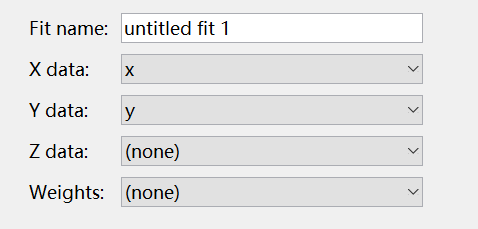

- **选择拟合曲线类型(在此选择线性拟合，基函数为**$1,x^2,x^{-2}$**)**

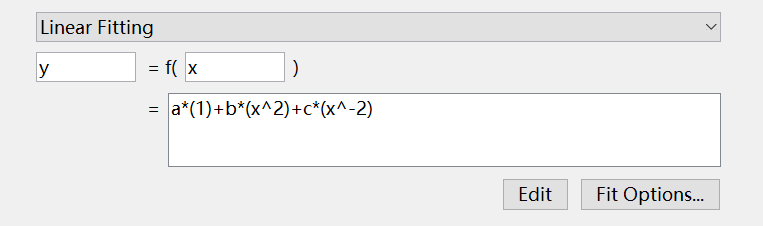

- **查看拟合结果(Result栏)**

- **导出拟合结果：cftool界面选项栏 —— 文件(F) —— Generate Code  即可导出代码文件。**

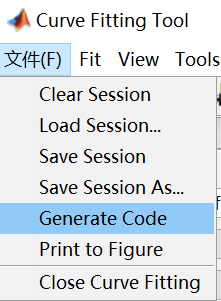

### 2.直方图(histogram)

clear;
data = readtable("./data/data4.csv");
data = data.Close;

subplot(2,2,1);
histogram(data)

subplot(2,2,2);
%用名称-值对组参数设置直方图的各种属性，如bin的颜色、透明度、归一化方式等
%在此将'Normalization'设置为'probability'进行归一化，使得各bin的高度为概率值，各bin高度之和为1
%更详细的说明请参阅说明文档页面"histogram"
histogram(data,10,'Normalization','probability')     %指定标量nbins，确定直方图的bin数

edges = 15:2:38;
subplot(2,2,3);
%在此将'FaceColor'设置为[0.9,0.5,0.2]
histogram(data,edges,'FaceColor',[0.9,0.5,0.2])  %指定向量edges，确定直方图bin的边界(左闭右开)

subplot(2,2,4);

%在此将'Normalization'设置为'pdf'进行归一化，使得bin的高度为概率密度的估计值，使得各bin面积和为1
histogram(data,10,'Normalization','pdf')    %指定标量nbins，确定直方图的bin数